
zc = 0.6 ;
g = 9.84;
Ts = 0.01;
% Define state space matrices
A = [0,1,0;0,0,1;0,0,0];
B = [0;0;1];
C = [1,0,-zc/g; 1,0,0; 0,1,0];      % zmp, pos, vel
D = [0;0;0];

% Create state space representation
lip_x = ss(A,B,C,D);

% Specify names
lip_x.InputName = 'xddd';
lip_x.StateName = {'x', 'xd', 'xdd'};
lip_x.OutputName = {'px', 'x', 'xd'};

% Discretize plant
lip_x_d = c2d(lip_x,Ts);
disp(lip_x_d);

  3×1 ss array with properties:

                A: [3×3 double]
                B: [3×1 double]
                C: [3×3 double]
                D: [3×1 double]
                E: []
           Scaled: 0
        StateName: {3×1 cell}
        StatePath: {3×1 cell}
        StateUnit: {3×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: [3×1 double]
               Ts: 0.0100
         TimeUnit: 'seconds'
        InputName: {'xddd'}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]



% Assign measured outputs and unmeasured outputs
lip_x_d = setmpcsignals(lip_x_d, 'MeasuredOutputs', 1, 'UnmeasuredOutputs',[2 3]);
% Step parameters

basedist = 0.381;
stepLength = 0.20;
zmpref = basedist+stepLength;
zmpref2 = stepLength - 2*zmpref;
stepTime = 0.7;
stepTime2 = 2*stepTime;

% MPC parameters
predictionHorizon = stepTime2/Ts;
numOutputs = 3;
initialState = [0;0;0];

% Create MPC controller object with sample time
mpc1 = mpc(lip_x_d,Ts);

-->The "PredictionHorizon" property of "mpc" object is empty. Trying PredictionHorizon = 10.
-->The "ControlHorizon" property of the "mpc" object is empty. Assuming 2.
-->The "Weights.ManipulatedVariables" property of "mpc" object is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property of "mpc" object is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property of "mpc" object is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 y3 


   Assuming no disturbance added to measured output channel #1.
-->The "Model.Noise" property of the "mpc" object is empty. Assuming white noise on each measured output channel.


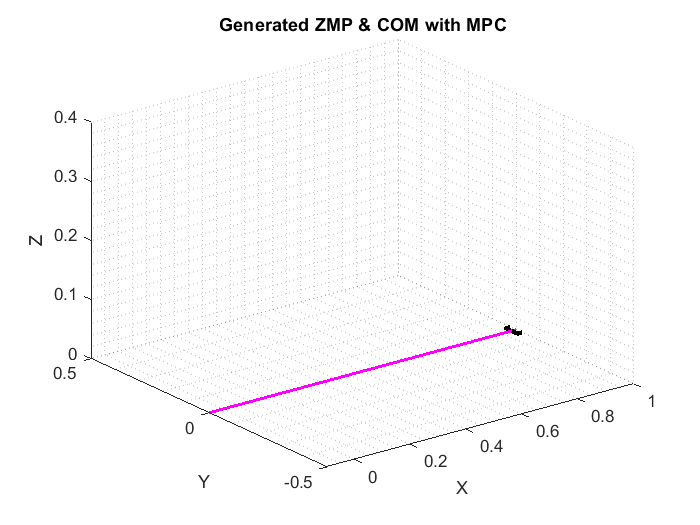

% Specify prediction horizon
mpc1.PredictionHorizon = predictionHorizon;
% Specify control horizon
mpc1.ControlHorizon = predictionHorizon;
% Specify nominal values for inputs and outputs
mpc1.Model.Nominal.U = 0;
mpc1.Model.Nominal.Y = [0;0;0];
% Specify weights
mpc1.Weights.MV = 0;
mpc1.Weights.MVRate = 0.05;
mpc1.Weights.OV = [1 0 0];
mpc1.Weights.ECR = 100000;

% open_system('testMPCWalkingPatternGen.slx');
sim('testMPCWalkingPatternGen.slx',10);


 ZMP = ZMPdata.signals(1,1).values;
 X_com = ZMPdata.signals(1,2).values;
 Vx_com = ZMPdata.signals(1,3).values;
 ZMP = ZMP(101:1001,2);
 X_com = X_com(101:1001,1);
 Vx_com = Vx_com(101:1001,1);


